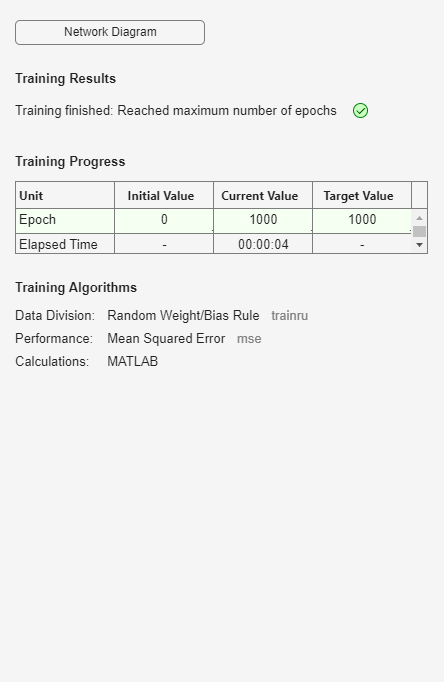

%竞争型网络（有目标分类）
%福冈与中国六城市的相似性比较（数据未经标准化）
clear                                       %清理内存
P=[15.7	16.3 17.2 18.8 17.9 16.3
970 1260 1422 1874 1698 976
2209 2085 1726 1709	1848 1239
-20.6 -17.3	-9.5 -4.9 -4.5 -4.6
1.9	2.8	4.6	8.0	7.5	5.6];                   %输入变量
net=newc(minmax(P),2);                      %创建六城市五变量二分类的竞争型网络
net.trainParam.epochs=1000;                 %指定最大训练次数
net=train(net,P);                           %训练网络

Y=sim(net,P);                               %数值仿真结果
Yc=vec2ind(Y)                               %给出分类向量

Yc =      2     2     1     1     1     2


Q=[16.2 1492 2000 -8.2 6.2]';               %输入福冈的信号
y_test=sim(net,Q);                          %福冈数值仿真
yc_test=vec2ind(y_test)                     %福冈归类结果

yc_test = 1